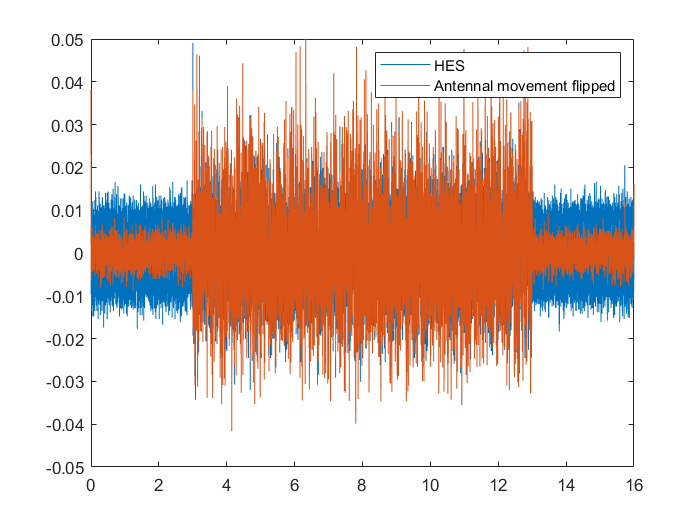

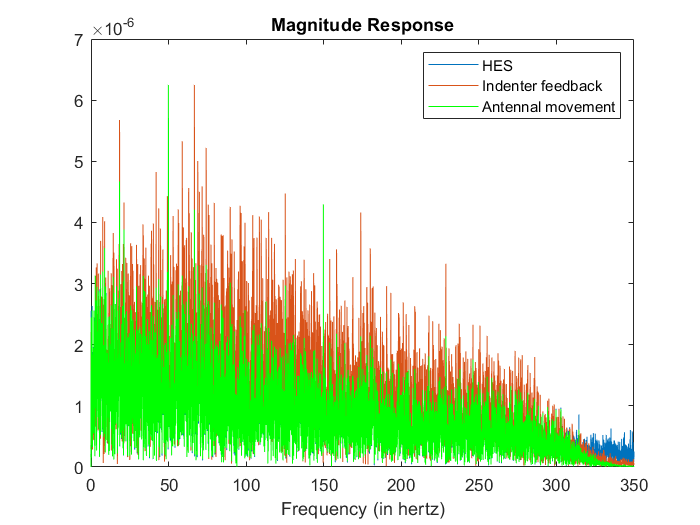

for idx=1
    
    fs = blwgn(idx).fs;
    trial_length = blwgn(idx).ON_dur + 2*blwgn(idx).OFF_dur;
    t = (0:1/fs:trial_length);
    
    hes = blwgn(idx).hes_data_unfilt(1,:);
    figure;
%     plot(t, hes-hes(1,1)); hold on;
%     hes = rand([1,160001]);
%     hes = butter_filtfilt(hes, 300, 10000, 4);
    hes = hes - mean(hes);
    plot(t, hes); hold on;
    stim_ifb = blwgn(idx).stim_ifb(1,:); 
    stim_ifb = stim_ifb-mean(stim_ifb);
    ant_mov = blwgn(idx).antennal_movement(1,:);
%     plot(t, -ant_mov+ant_mov(1,1));
    
    ant_mov = ant_mov - mean(ant_mov);
    plot(t, -ant_mov);
    legend('HES', 'Antennal movement flipped');
    
    
    
    
    
%     t = (0:1/fs:16);
    N = length(t);
    dF = fs/N;                      % hertz
    f = -fs/2:dF:fs/2-dF;
    hes_fft = fftshift(fft(hes));
%     hes_rand = hes - mean(hes);
%     hes_rand_fft = fftshift(fft(hes_rand));
    stim_ifb_fft = fftshift(fft(stim_ifb));
    ant_mov_fft = fftshift(fft(ant_mov));
    
    figure;
%     plot(f,abs(hes_rand_fft)/(N*max(abs(hes_rand_fft)))); hold on;
    plot(f,abs(hes_fft)/(N*max(abs(hes_fft)))); hold on;
    
    plot(f,abs(stim_ifb_fft)/(N*max(abs(stim_ifb_fft))));
    plot(f,abs(ant_mov_fft)/(N*max(abs(ant_mov_fft))), 'g');
    xlabel('Frequency (in hertz)');
    title('Magnitude Response');
    xlim ([0 350]);
    legend ('HES', 'Indenter feedback','Antennal movement');
% legend('Random data', 'Filtered data');


end